Limpar 

close all
clear
clc

# Analise CC para emisro comum com polarização por divisor de tensão

## ESTAGIO 1:

Figura 1- Circuito base

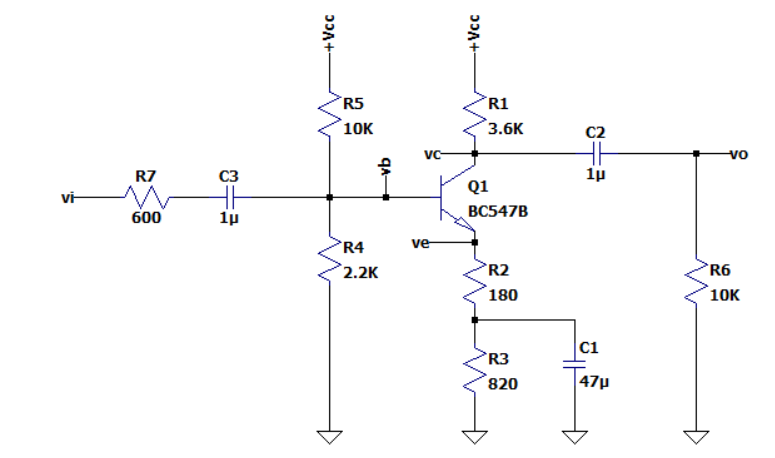

## ** Calc Analise CC (DC)**

Figura 2- Circuito para analise CC

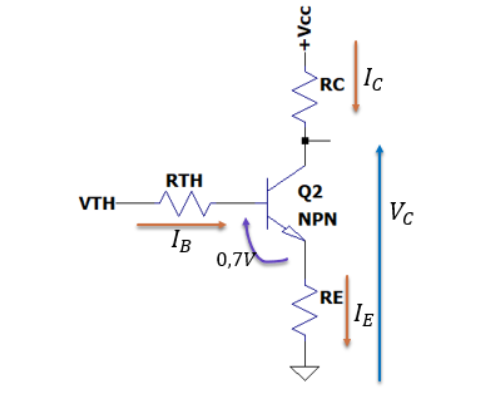

### Valores dos componentes:

R5E1 = 33e+3;%%Rth
R4E1 =2.2e+3;%%Rth
ReE1 = 10;
R3E1 = 190;
REE1 = ReE1+R3E1;%% R2+R3
VccE1 = 18;%%Variavel de entrada
BE1 = 290; % Beta para o calc
VbeE1 = 0.7; 
VceE1 = 5; %data sheet


### Equivalentes de TH

Vth = (R4E1/(R5E1+R4E1))*VccE1

Vth = 1.1250

Rth = ((1/R5E1)+(1/R4E1))^-1

Rth = 2.0625e+03

### Correntes

Ib = (Vth-VbeE1)/(Rth+REE1*(BE1+1))

Ib = 7.0525e-06

Ic = (BE1+1)*Ib

Ic = 0.0021

Ie = Ic

Ie = 0.0021

### Tensões CC

Vb = Vth

Vb = 1.1250

Ve = REE1*Ie

Ve = 0.4105

Vc = VceE1+Ve

Vc = 5.4105

## **Calc Analise CA (AC)**

Figura 3- Circuito para analise CA

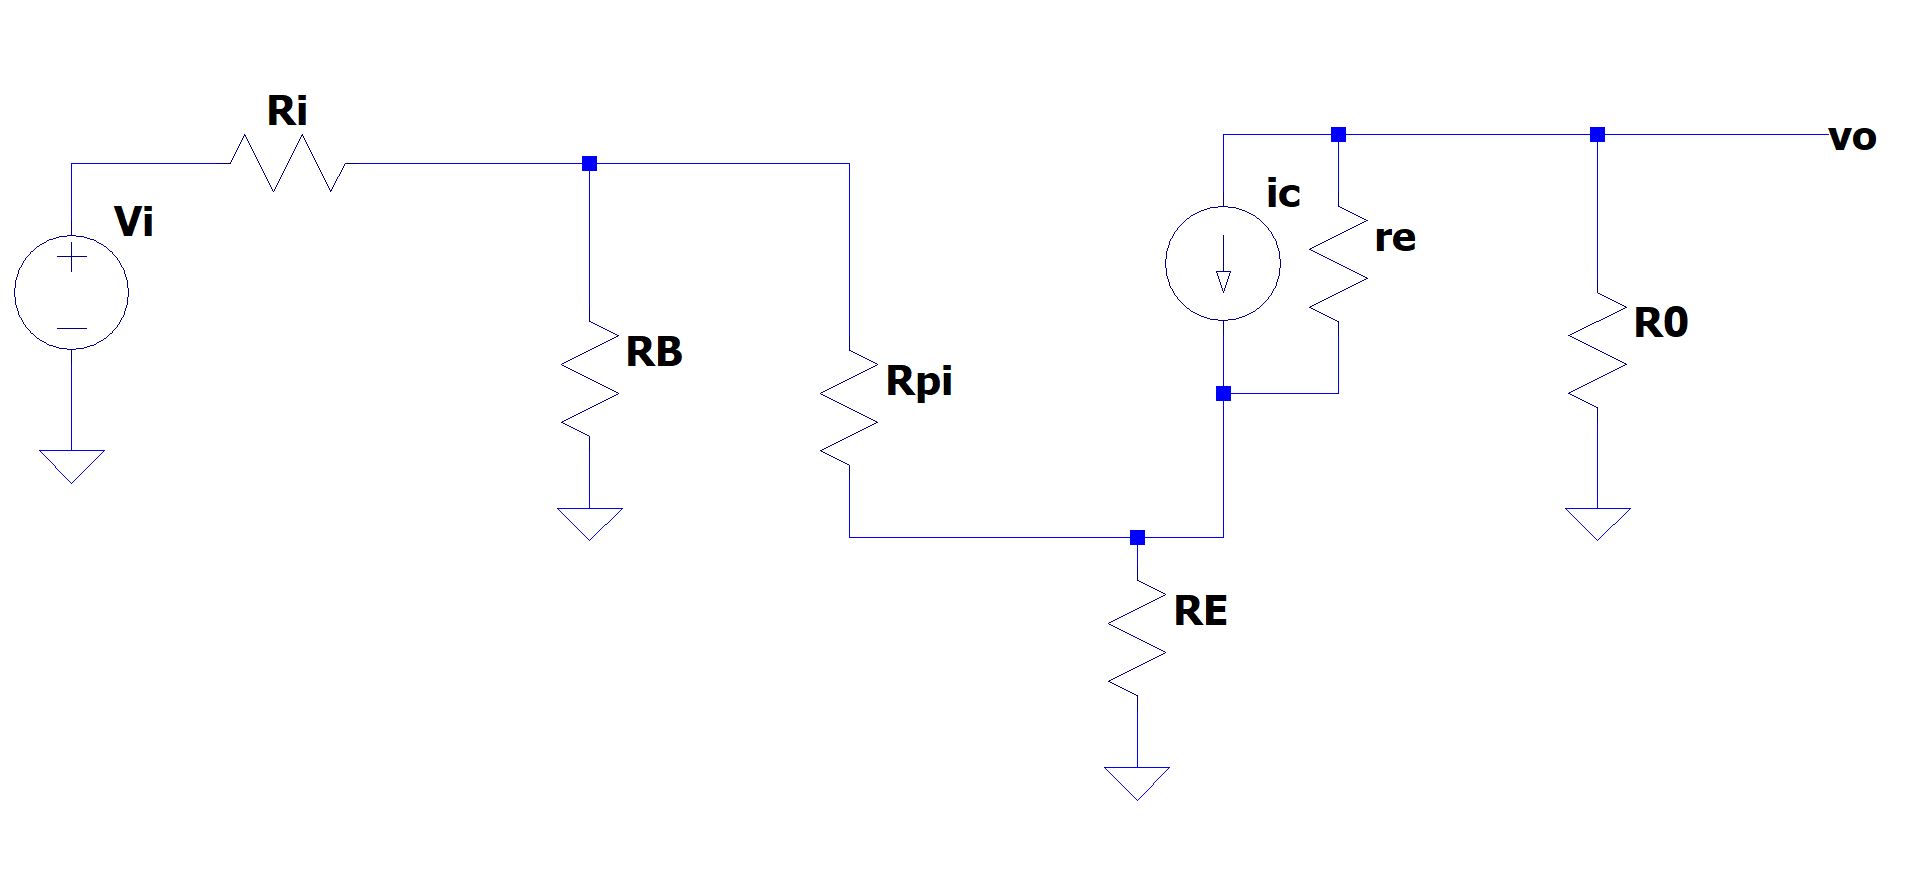

### Valores dos componentes 

*Obs.: todos os valores de componentes possuem a variavel com nome correspondente ao circuito apresentado na figura 1.

Ri = 100; %valor de entrada da figura 1
RL = 1.3e+3;%valor de entrada da figura 1
RC = 18e+3;%valor de entrada da figura 1
RB = Rth; %calculado
R0 = ((1/RL)+(1/RC))^-1%calculado R0

R0 = 1.2124e+03

ReE1 = 180; %valor de entrada da figura 1  R2
VT = 22e-3;%% Tensão termica dado no datasheet VT = (K*T)/q
vi = 35e-3

vi = 0.0350

### calculo do re e rpi:

re = VT/Ie

re = 10.7198

rpi = (BE1+1)*re

rpi = 3.1195e+03

### **Calculo para CA**

Zb = (BE1+1)*(ReE1+re)

Zb = 5.5499e+04

vb = (((1/RB)+(1/Zb))^-1/(Ri+((1/RB)+(1/Zb))^-1))*vi

vb = 0.0333

ib = vb/Zb

ib = 6.0044e-07

ic = BE1*ib

ic = 1.7413e-04

ie = (-vb+rpi*ib)/ReE1

ie = -1.7473e-04

Av = -BE1*((R0)/(Ri+((Ri/RB)+1)*(BE1+1)*(ReE1+re)))

Av = -6.0320

vo = Av*vi

vo = -0.2111

Z0 = R0

Z0 = 1.2124e+03

ve = ReE1*ie

ve = -0.0315

vc=vo

vc = -0.2111

Zi = Ri+((1/RB)+(1/rpi))^-1

Zi = 1.3416e+03

Calculo dos Capacitores estagio 1:

fl = 20;
C1 = (1/2*pi)*(1/(0.1*fl*Ri+((1/R1)+(1/R2)+(1/BE1*re))^-1))
C2 = (1/2*pi)*(1/(0.8*fl*(((1/REE1)+1/((re+((1/R1)+(1/R2)+(1/Ri))^-1)))^-1)))
C3 = (1/2*pi)*(1/(0.1*fl*(RC+RL)))

## ESTAGIO 2